Here are some points that we could consider to be observations of an unknown function on $[-1,1]$.

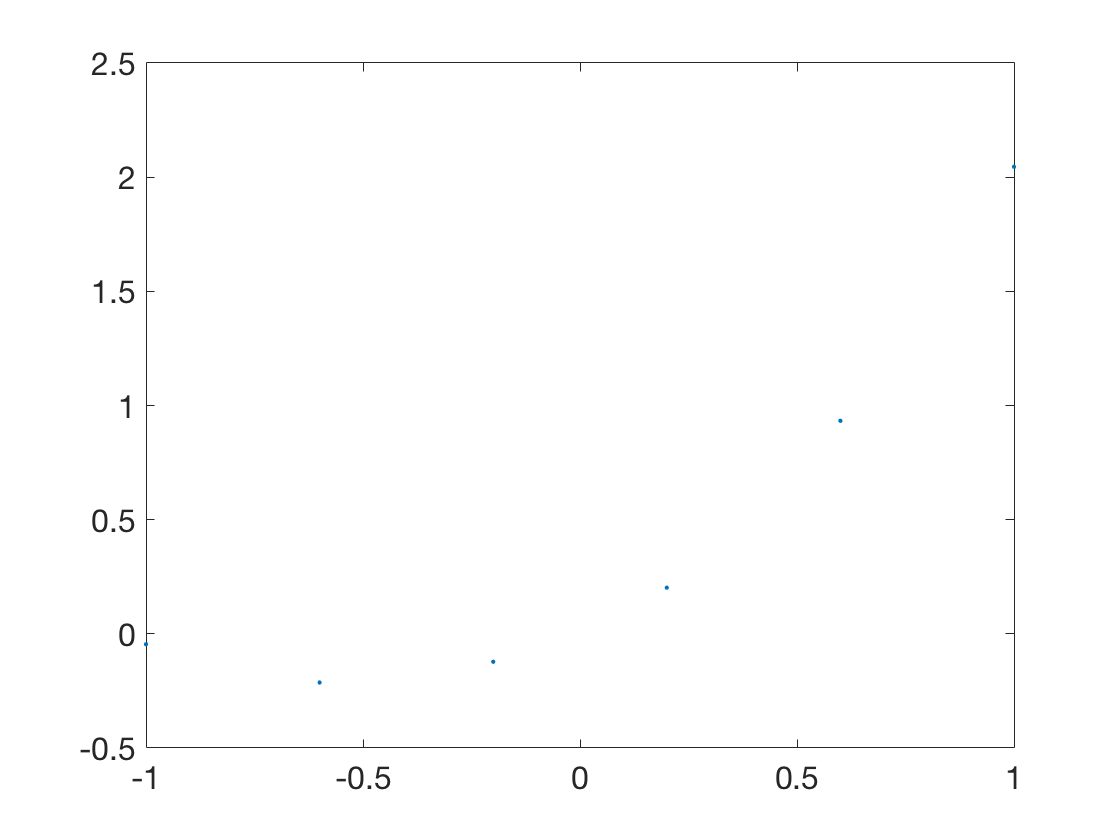

n = 5;
t = linspace(-1,1,n+1)';  y = t.^2 + t + 0.05*sin(20*t);
plot(t,y,'.')

The polynomial interpolant, as computed using `polyfit`, looks very sensible. It's the kind of function you'd take home to meet your parents. The interpolant plot is created using `fplot`.

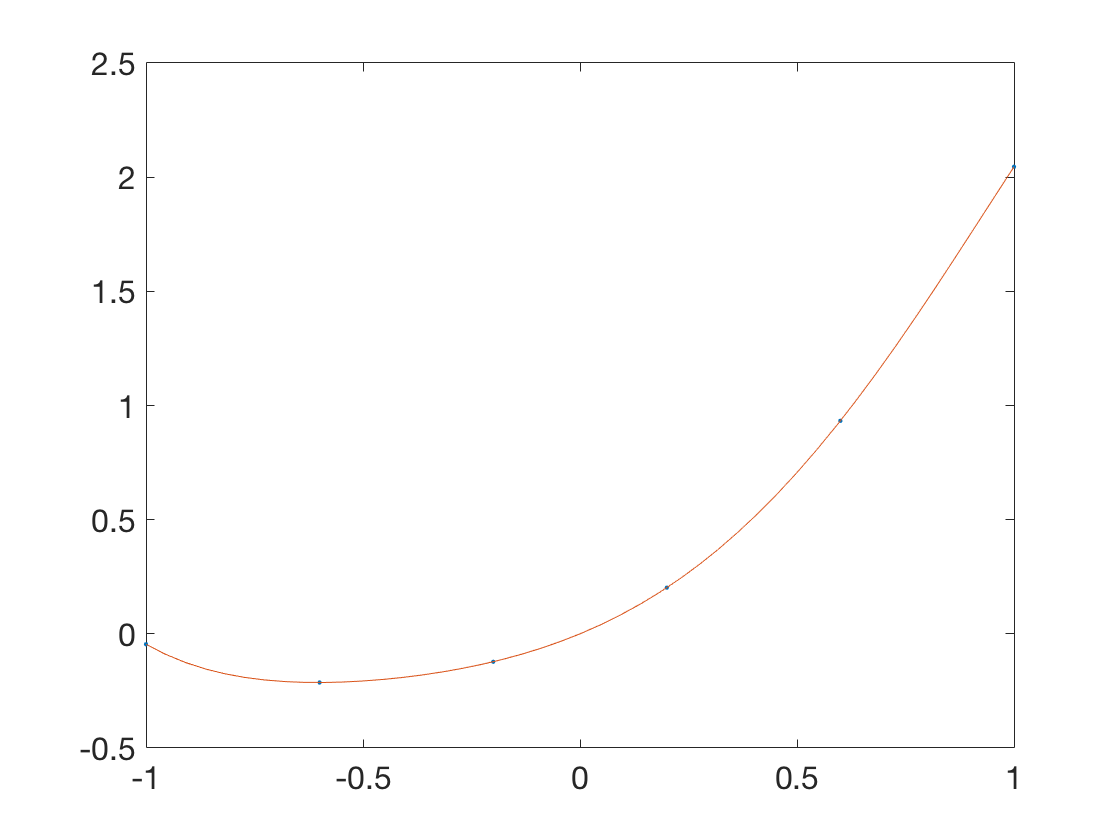

c = polyfit(t,y,n);     % polynomial coefficients
p = @(x) polyval(c,x);
hold on, fplot(p,[-1 1])

But now consider a different set of points generated in almost exactly the same way.

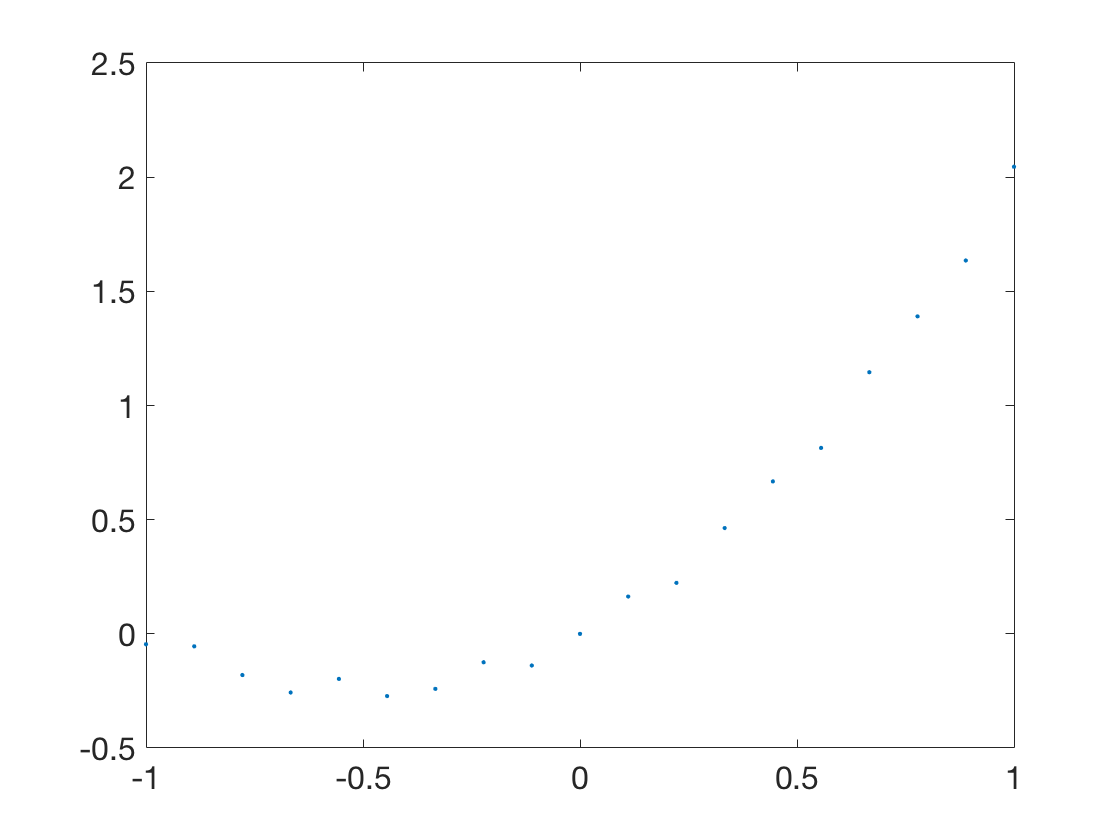

n = 18;
t = linspace(-1,1,n+1)';  y = t.^2 + t + 0.05*sin(20*t);
clf, plot(t,y,'.')

The points themselves are unremarkable. But take a look at what happens to the polynomial interpolant.

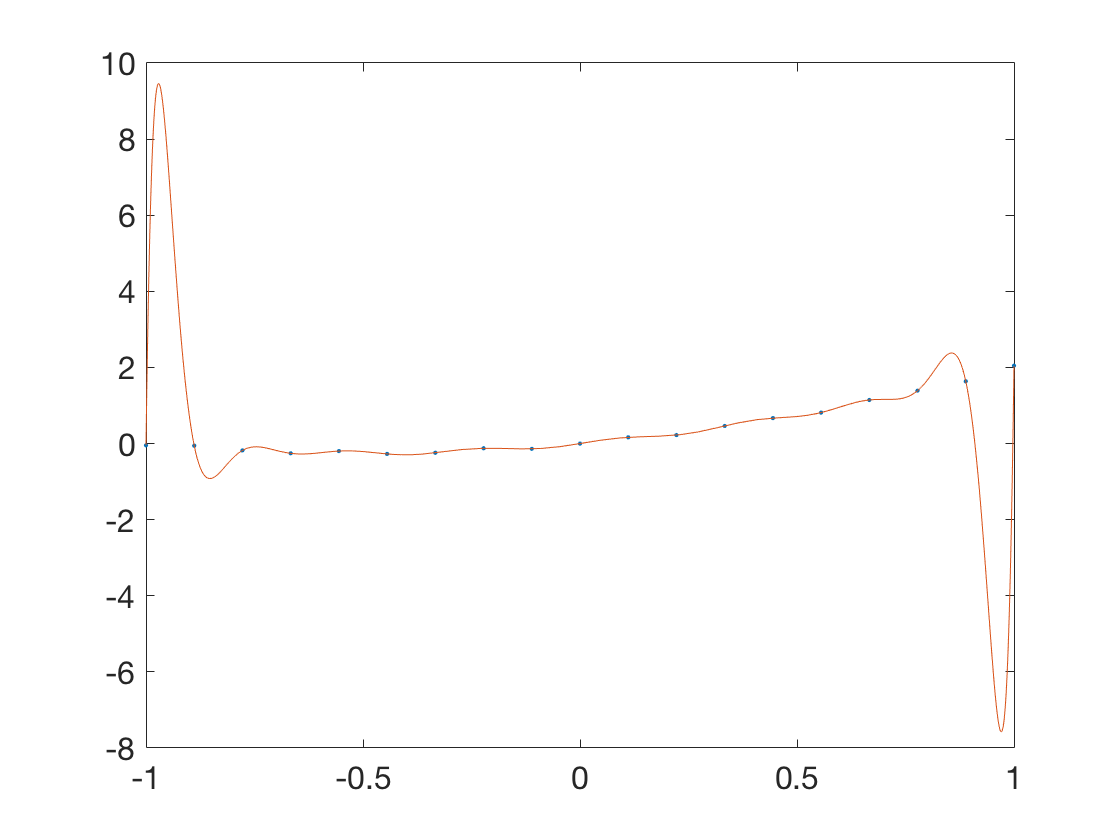

c = polyfit(t,y,n);     % polynomial coefficients
p = @(x) polyval(c,x);
hold on, fplot(p,[-1 1])

Surely there must be functions that are more intuitively representative of those points!